# DSP Lab 04

# Processing of 3D Signals (Video Sequences)

## 1. Objective

Students should understand and be able to operate with video data in Matlab.

## 2. Theoretical aspects

### 2. 1 Representation of video sequences 

A video sequence is just a sequence of images displayed with speed high enough to "fool the eye" into thinking it sees a continuous movement.

As a consequence, a video sequence can be represented as an array of images. The images are known as "**frames**".

**Note**: there is a difference between how a video sequence is stored to disk (with compression) and the raw uncompressed data. Here we talk about the uncompressed video data.

#### Grayscale video

For simplicity, we consider only grayscale video in this laboratory. Since a grayscale image is a matrix, a grayscale video can be represented as a 4D **tensor** with dimensions (H, W, 1, NoF), where:

- H = height of video (number of rows)

- W = width of image (number of columns)

- NoF = number of frames (number of distinct images in the video).

For example, V(20, 50, 1, 7) is the pixel value for the pixel at row 20, column 50, in the 7th frame.

#### Color video

In case of a color video, the data structure is a tensor with dimensions (H, W, 3, NoF). We have three components for the RGB values. 

For example, V(20, 50, 2, 7) is the Green value (2) of the pixel at row 20, column 50, in the 7th frame of the video.

### 2.2 Matlab functions for video handling

There are multiple ways of handling video data in Matlab, depending on how it is represented,. In the following, we restrict only the case of grayscale video represented as a 3D tensor.

In Matlab, we read an image file with `imread()`. 

We can display a matrix as an image with `imshow()`. 

We save an image to disk with `imwrite()`. 

If the matrix contains integer values going to 255 (check this in the Workspace), it is typical to convert the values to double and divide them to 255, so that all the values will be floating-point numbers between 0 and 1.

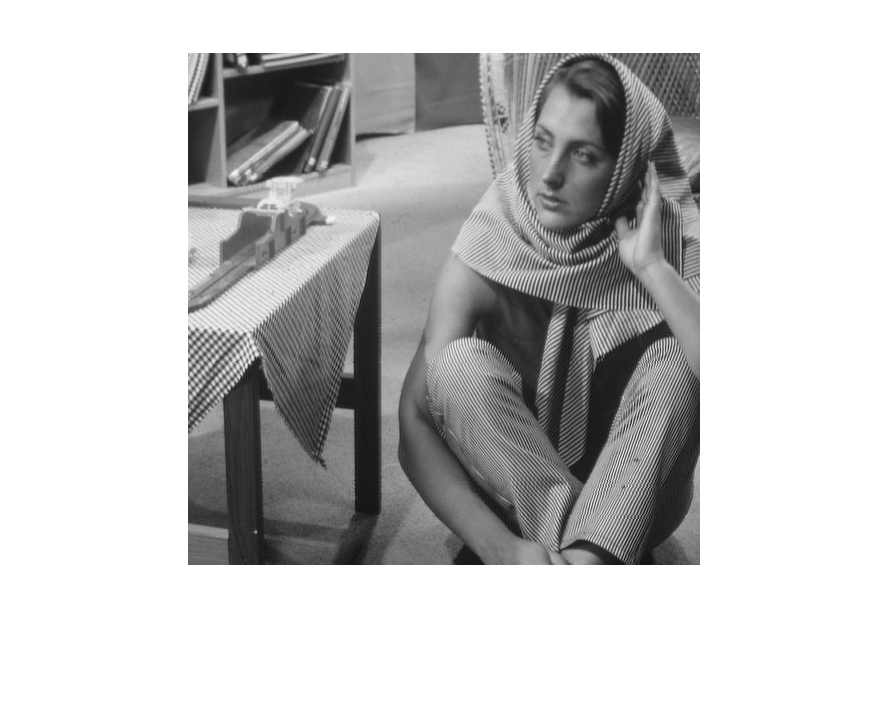

% Load a grayscale image 
I = imread('barbara.png');

% Convert values to double and divide by 255
I = double(I)/255;

% Display the image
imshow(I)

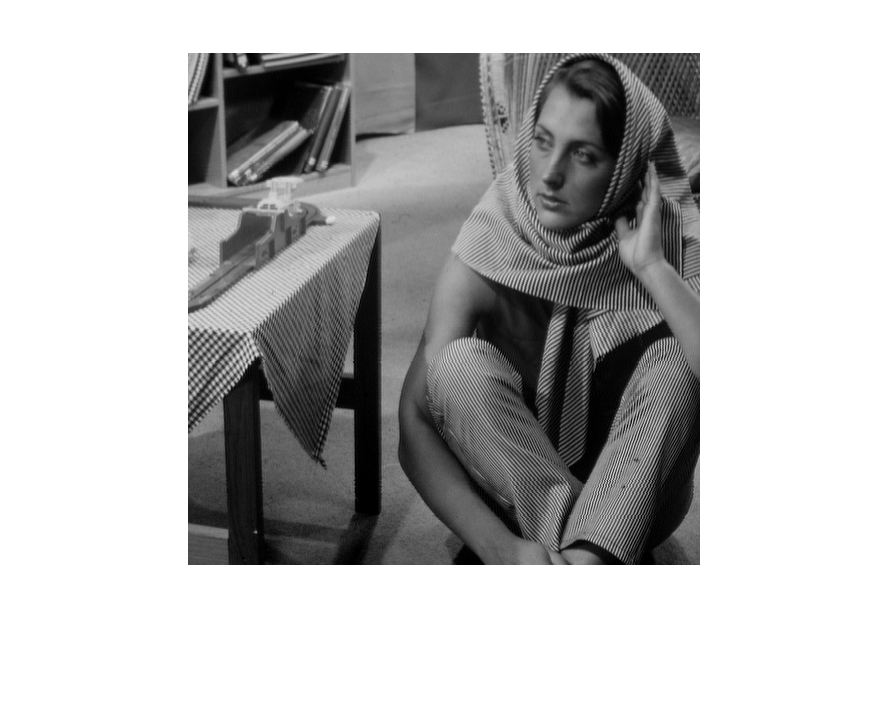


% Darken the image by subtracting 0.1 from all pixels
I2 = I - 0.1;  % I2 is still a matrix

% Display the new image
figure
imshow(I2)


% Write modified image to disk
imwrite(I2, 'barbara_modif.png')

### 2.3 Concatenate in any dimension

The Matlab function `cat()` does concatenation of arrays along any specified direction.

A = rand(2,3);
B = rand(2,3);
C1 = cat(1,A,B);  % Concatenate across first dimension => size is (4,3)
size(C1)

ans =      4     3


C2 = cat(2,A,B);  % Concatenate across second dimension => size is (2,6)
size(C2)

ans =      2     6


C3 = cat(3,A,B);  % Concatenate across third dimension => size is (2,3,2)
size(C3)

ans =      2     3     2


## 3. Exercises

1. Create and display a chessboard image with each square having size $5 \times 5$ pixels.

2. Modify the chessboard image to have light gray and dark gray instead of white and black.

3. Create a $200 \times 300$ color image representing the Romanian flag (3 stripes of blue, yellow, red). Create the image using the following steps:

- Create three matrices for the R, G, B components of the image

- Concatenate the three matrices across third dimension, into a 3D tensor

4. Load the `Lena512.bmp` image and display it.

5. Construct a new image based on the `Lena`, but in which each pixel value is set as a linear combination of the original pixels around it, as in the following equation. Ignore the first and last row/column (it makes life simpler here). Display the resulting image. How did it change?


$$y[i,j] = \frac{1}{9}x[i-1,j-1] + \frac{1}{9}x[i-1,j] + \frac{1}{9}x[i-1,j+1] \\
        +\frac{1}{9}x[i,j-1]   + \frac{1}{9}x[i,j]   + \frac{1}{9}x[i,j+1] \\
        +\frac{1}{9}x[i+1,j-1] + \frac{1}{9}x[i+1,j] + \frac{1}{9}x[i+1,j+1]$$


6. Repeat Exercise 2 but change the values of the coefficients used in the equation to the following:


$$\pmatrix{ 0 & -1 & 0 \cr  -1 & 5 & -1 \cr  0 & -1 & 0}
$$


7. Repeat Exercise 2 but change the values of the coefficients to


$$$\pmatrix{
 0 & -1 & 0 \cr
 -1 & 5 & -1 \cr
 0 & -1 & 0}$$$


8. Repeat Exercise 2 but change the values of the coefficients to


$$$
\pmatrix{
 -1 & -1 & -1 \cr
 -1 & 8 & -1 \cr
 -1 & -1 & -1
}
$$$


9. Repeat Exercise 2 but change the values of the coefficients to


$$$
\pmatrix{
 0 & -1 & -0\cr
 -1 & 4 & -1 \cr
0 & -1 & 0
}
$$$


## 4. Final questions

1. TBD